# Data loading

load CRIM.mat
Y = CRIM; 

## Figure 3 left panel: Traditional non robust PCA

The first PC already explains more than 0.95^v variability
In what follows we still extract the first 2 PCs


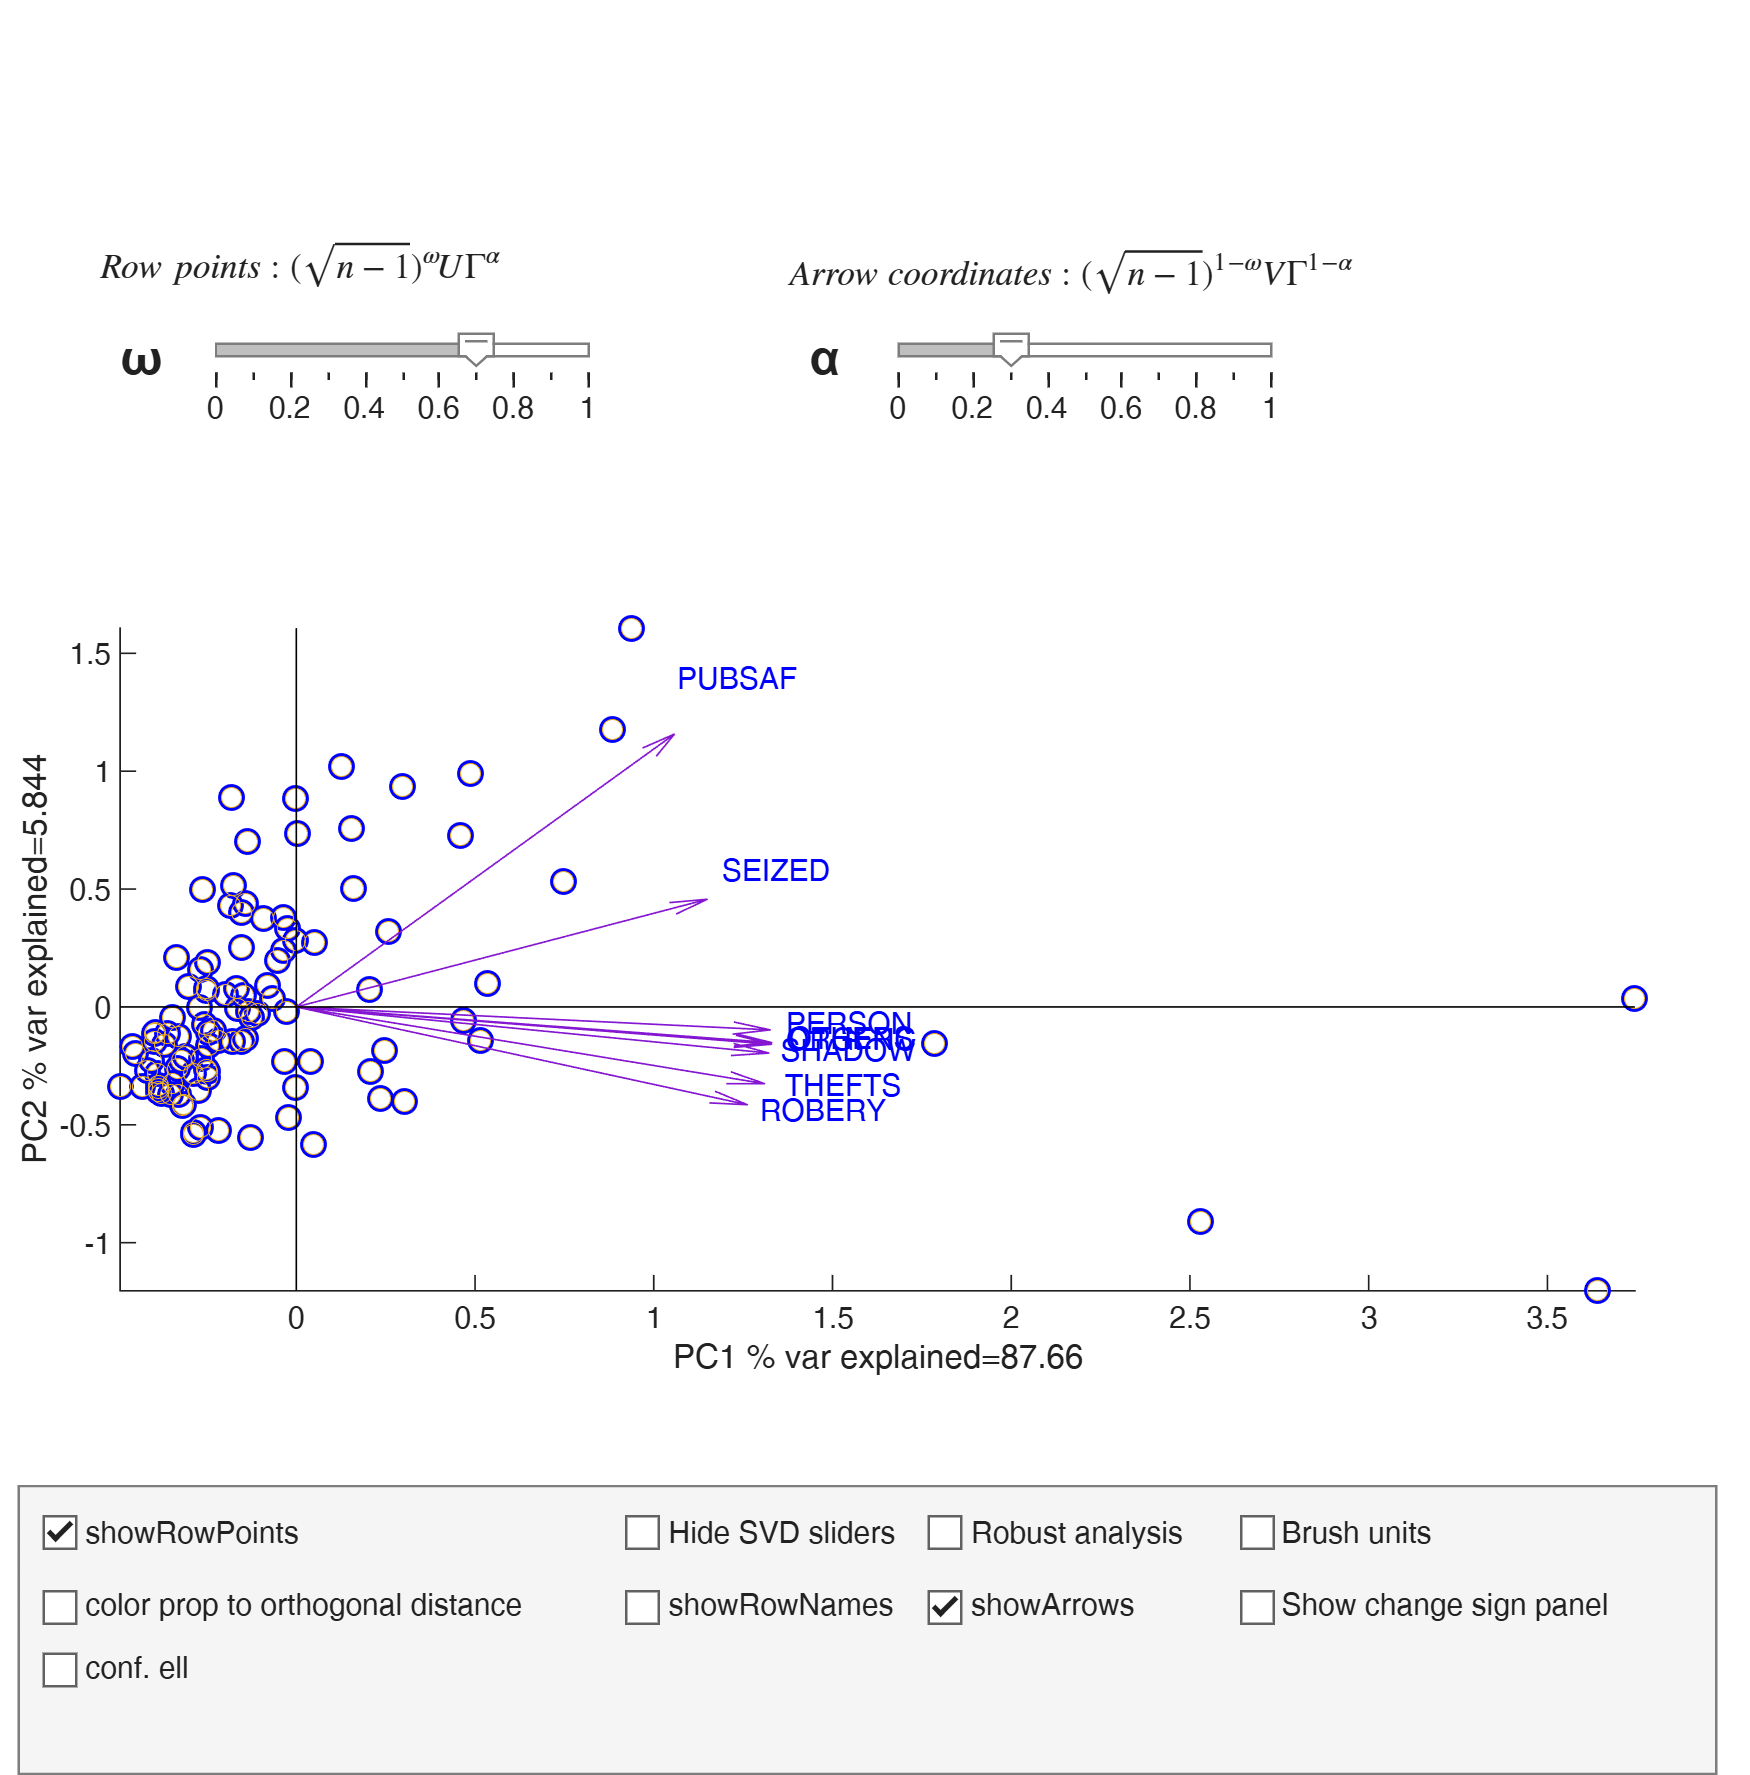

out=pcaFS(Y,"plots",false,"dispresults",false);

## Outlier detection

close all
outFSM=FSM(Y{:,:},'bonflev',0.9999,'plots',0);

-------------------------
Signal detection loop
$d_min$(101,106)>99% Bonferroni level
----------------------------
Final output
Number of units declared as outliers=5


## Figure 3 right panel: Robust PCA analysis

The first PC already explains more than 0.95^v variability
In what follows we still extract the first 2 PCs


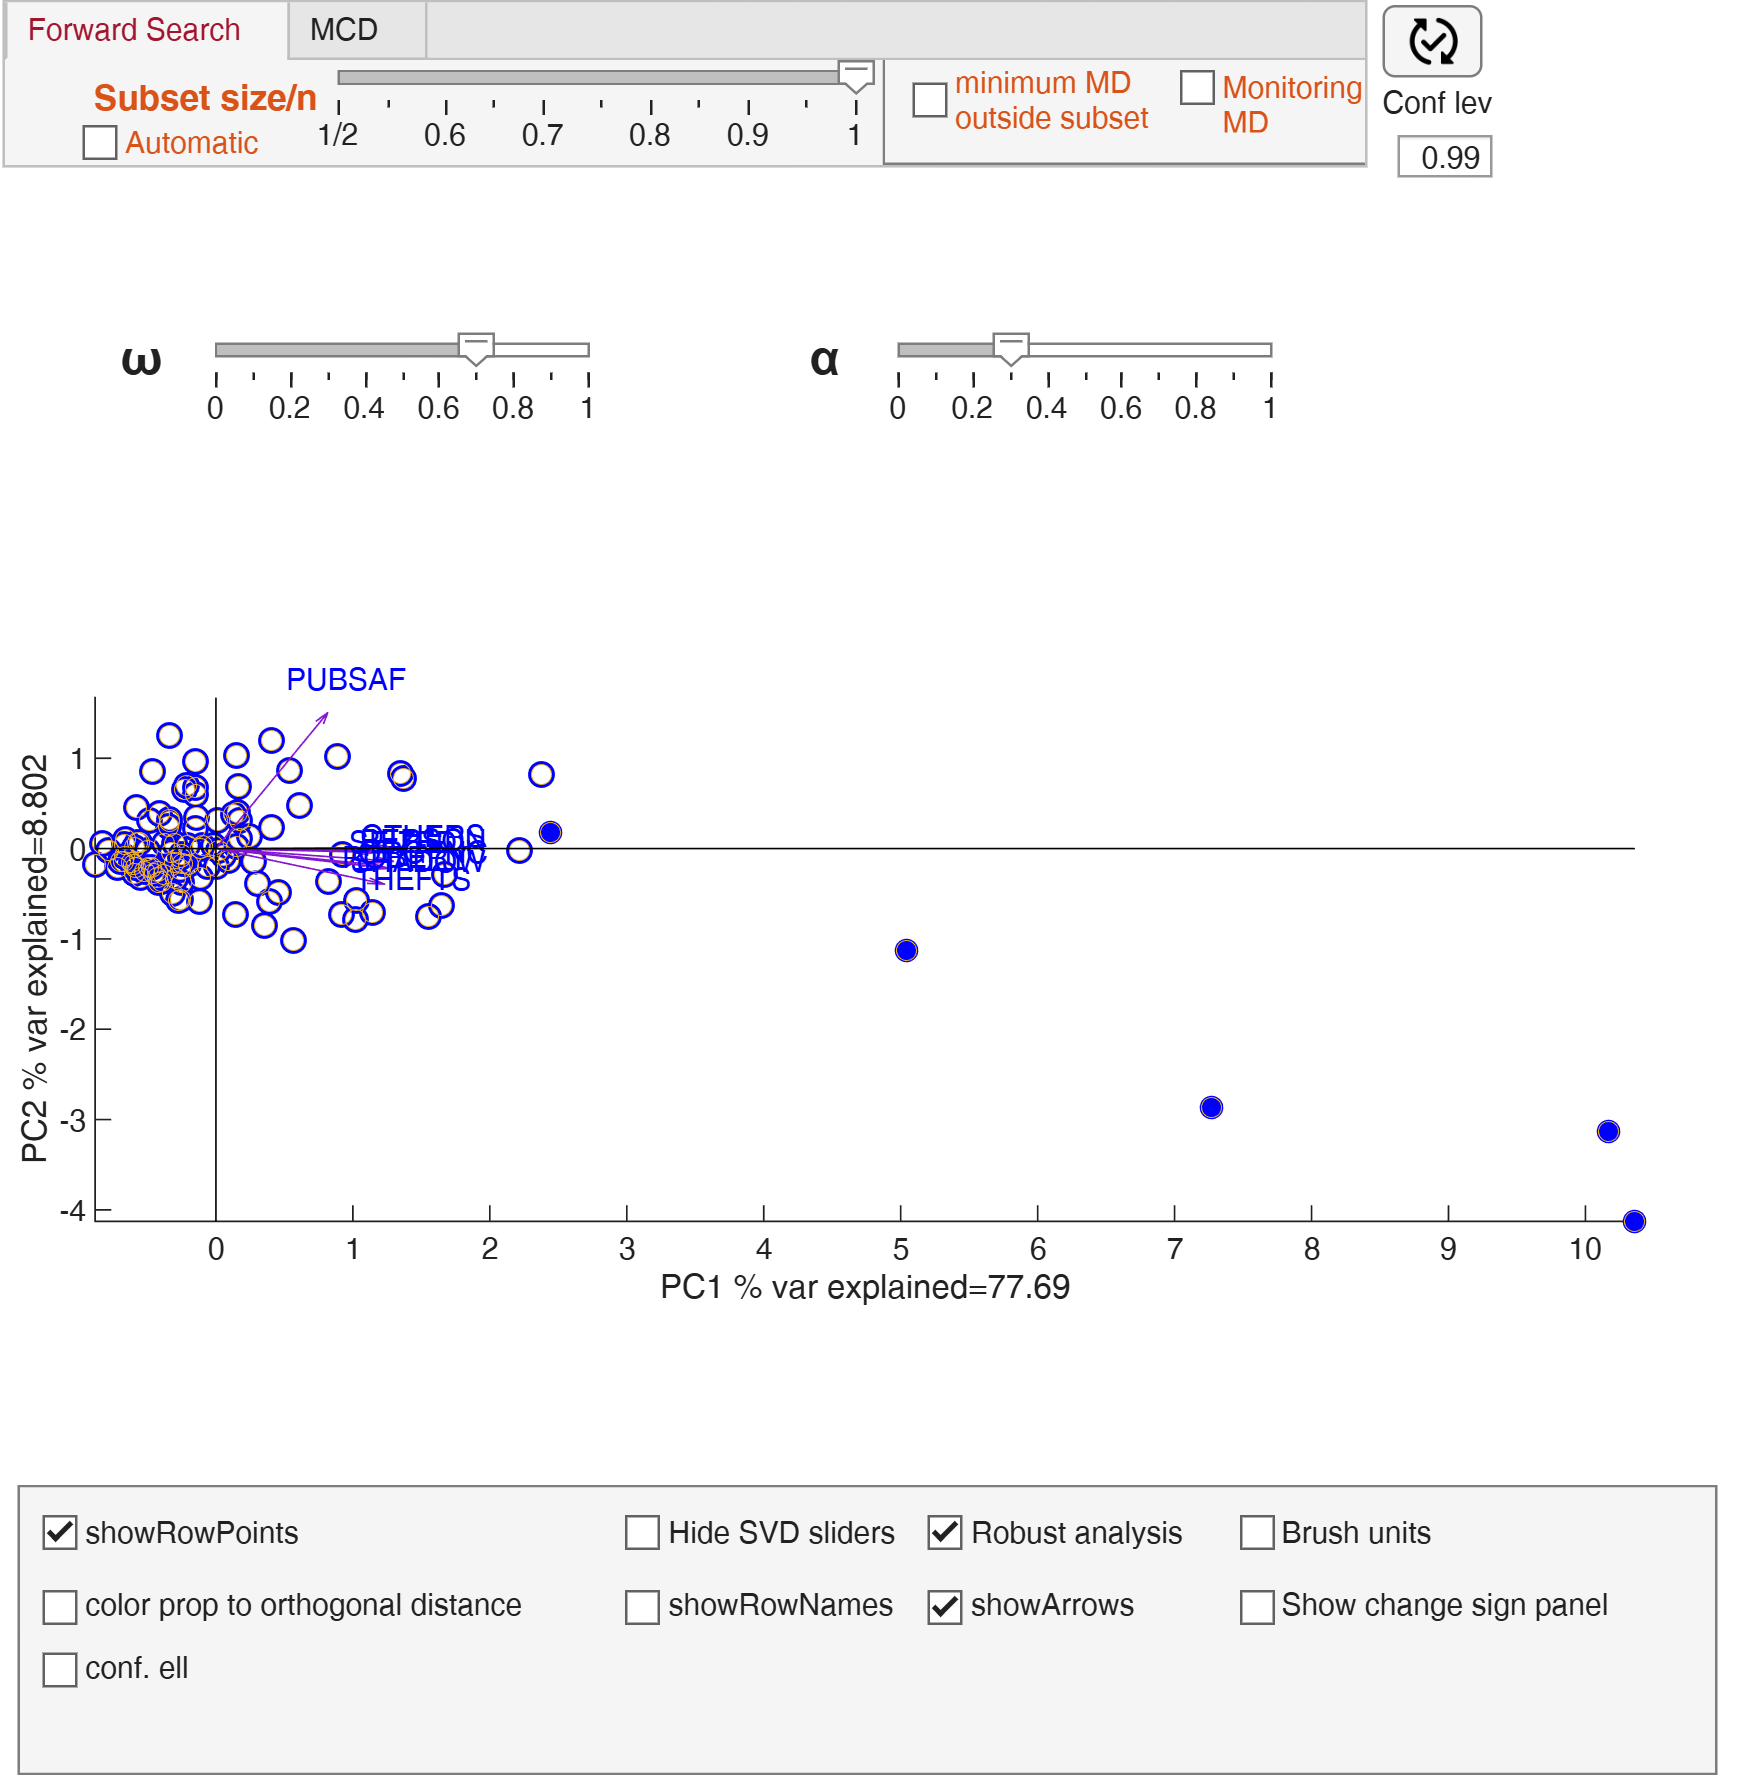

robust=struct;
n=height(Y);
seq=1:n;
robust.bsb=setdiff(seq,outFSM.outliers);
outFS=pcaFS(Y,"robust",robust,"plots",false,"dispresults",false);

% In the biplot APP to reproduce exactly the right panel of Figure 3
% 1) select the chechbox conf.ell.
% 2) select omega=0.3 in the top slider bar

## Figure 2: personalized scatter plot matrix with the 2 groups

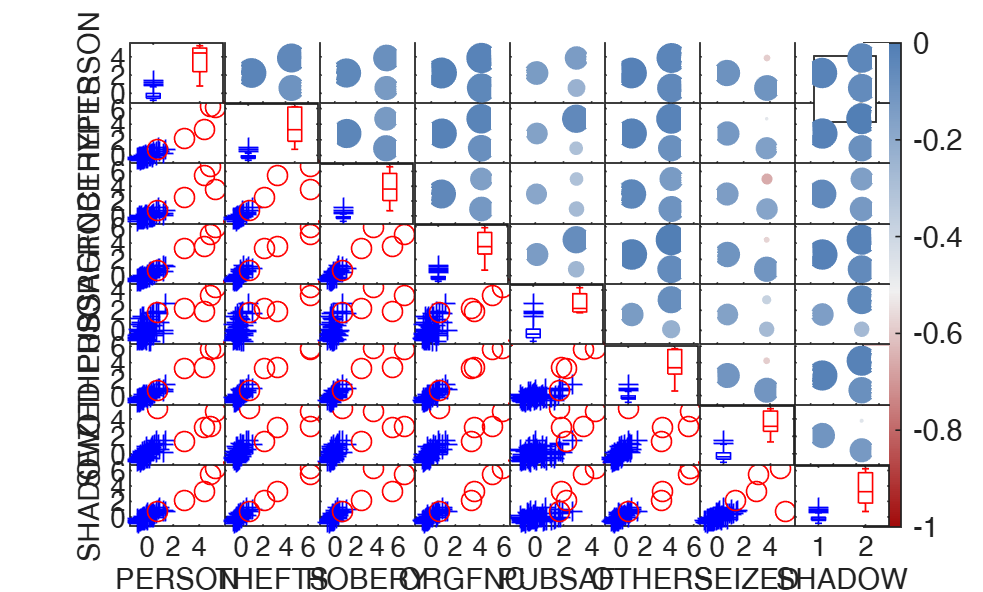

close all
group=ones(n,1);
group(outFSM.outliers)=2;
typespm=struct;
typespm.upper='circle';
spmplot(Y,'group',group,'dispopt','box','typespm',typespm);